# Exercise 2

## On the Road

### About This Exercise

While we can think of a graph as cells and the edges that connect them, we may alternatively want to think of points in the map and lines that connect them. After all, "roads" are what are actually going to be used to get from one place to another. Thus, another way to create a graph based on a map is to select points on the map as the nodes, where paths connecting those points are the edges. 

For this exercise, you will create a roadmap from the trapezoidal cell decomposition from the previous exercise. One way might be to select the centroids of the regions as the nodes and connect them to make the edges. However, there is no guarantee that the physical paths represented by the edges do not hit any obstacles. Thus, if instead we travel from edge to edge, we can avoid the obstacles. The function you created in the previous exercise already calculates the centers of the vertical paths that were calculated, so in this exercise, you will take those points and make them into a graph.

**By the end of this exercise, you'll be able to: **

- **Create a "road map" of waypoints using a trapezoidal cell decomposition.**

### Roadmap Graph

Given the output from the trapezoidalCells function, we would like to create a roadmap graph that connects the midpoints of the verticle edges of each cell. Each entry in the node struct contains one of the midpoints in the node.xy field. Also, for the first and last enties of node we included the mipoint of the leftmost and rightmost regions, as we do not want to have any points on the boundary of the map.

 [► Complete the roadmapGraph function](matlab:open('./roadmapGraph.mlx')) to generate a graph given the nodes and the polyvec representing the obstacles.

Once roadmapGraph is complete, this first section repeats what we did in the previous exercise to set up the inputs to the new function.

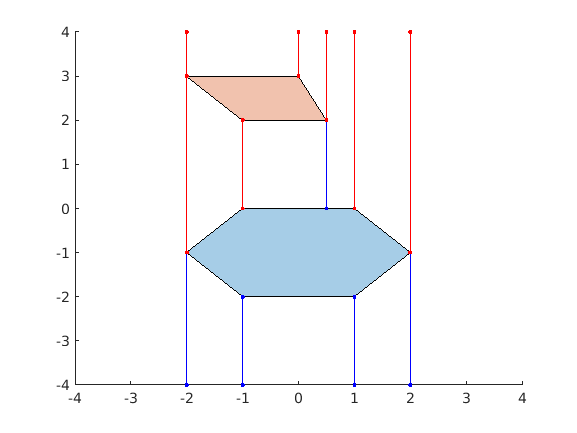

clear
close all
lim = 4;
p1x = [-2  -1 1 2 1 -1];
p1y = [0 1 1 0 -1 -1]-1;
p2x = [-2 0 .5 -1];
p2y = [3 3 2 2];

obstacle(1).px = p1x;
obstacle(1).py = p1y;
obstacle(2).px = p2x;
obstacle(2).py = p2y;

[polyvec, node, nodes_xy] = trapeziodalCells(obstacle, lim);

Now we can call roadmapGraph to plot the graph superimposed on the cell decomposition plotted by trapezoidalCells.  

G = roadmapGraph(node, lim, polyvec);

This will plot the graph at the node locations, with edges sized according to their weights

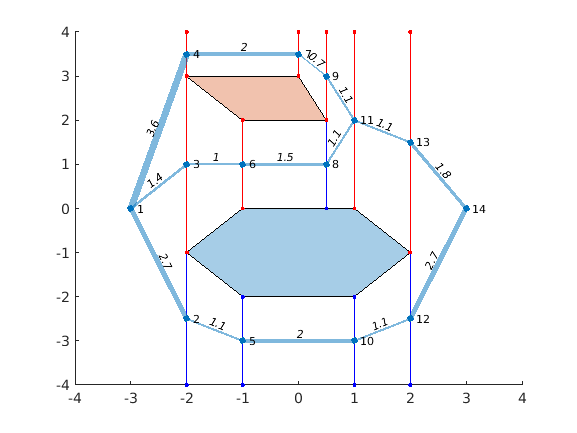

LWidths = 5*G.Edges.Weight/max(G.Edges.Weight);
plot(G,'XData',nodes_xy(1,:),'YData',nodes_xy(2,:),'EdgeLabel',str2num(num2str(G.Edges.Weight,'%.1f')),'LineWidth',LWidths)

### Finished!

Now your graph has nodes that represent specific waypoints in the physical map, and the edges between the nodes represent the straight-line routes between waypoints where we avoid obstacles. In the next exercise, you will implement a different method of generating a roadmap from the obstacles.